## **Econ 623: Computer Assignment 2**

## *Nond Prueksiri*

**Preparing Workspace**

clear;  
close all; 
clc;
cd('C:\Users\nprue\Desktop\econ623\cas2');
warning('off','all');


**Problem 1a - ***LBTest Function*

The function LBtest.m is as follows:

% function [Qstat, pval, corr] = LBtest(X,L)
%    corr = zeros(L,3);
%    T = size(X,1);
%
%    ## CALCULATE SAMPLE CORRELATIONS ##
%    samplecorr = autocorr(X, 'NumLags', L);
%    for j = 1:L
%        corr(j,1) = samplecorr(j+1);
%    end
%
%    ## BARTLETT STANDARD ERROR ##
%    se  = 1/sqrt(T);
%    for j = 1:L
%        corr(j,2) = corr(j,1)/se;
%        corr(j,3) = 1.96*se;
%    end
%    
%    ## CALCULATE Ljung-Box STATS (Q Stats) ##
%    lhosq = zeros(L,1);
%    for j = 1:L
%        lhosq(j) = corr(j,1)^2*(1/T-j);
%    end
%    sumlho = sum(lhosq);
%    Qstat = T*(T+2)*sumlho;
%    
%    ## CALCULATE P-VALUE FROM Q-STATISTICS ##   
%    pval = chi2cdf(Qstat,L);
%    
% end

**Problem 1b - ***Robust* *LBTest Function*

The function robustLBtest.m is as follows:

%function [chi2stat, pval, ci] = robustLBtest(X,L)
%T = size(X,1);
%
% ## Use mlag.m to obtain the lag matrices for the regressions on the lags
% using Newey-West Standard errors ##
%
%lagged_data = mlag(X,L,mean(X));
%
% ## regressions on the lags using Newey-West Standard errors ##
%nwresult = nwest(X(L+1:end),[ones(T-L,1),lagged_data(L+1:end,:)],L+3);
% 
% ## Calculate for the Wald Test Statistic ##
%chi2stat = nwresult.beta(2:end)'*(nwresult.vcv(2:end,2:end)\nwresult.beta(2:end));
%
% ## Return P-value from chi-2 statistic
%pval = chi2cdf(chi2stat,L);
%
% ## Obtain 95% Confidence Interval from Newey-West Standard Deviation ##
%ci = 1.96*(diag(nwresult.vcv).^0.5);
%end



**Problem 1c -*** Plotting Data*

findata = csvread('findata2.csv', 1,0);
findata(findata==0) = nan;
clean_dat = rmmissing(findata);
usdthb = clean_dat(:,2);
usdgold = clean_dat(:,3);
setbkk = clean_dat(:,4);

retthb = log(usdthb(2:end)./usdthb(1:end-1));
retgold = log(usdgold(2:end)./usdgold(1:end-1));
retset = log(setbkk(2:end)./setbkk(1:end-1));

retthb_sq = retthb.^2;
retgold_sq = retgold.^2;
retset_sq = retset.^2;

- **Series 1A** - USDTHB (Return)

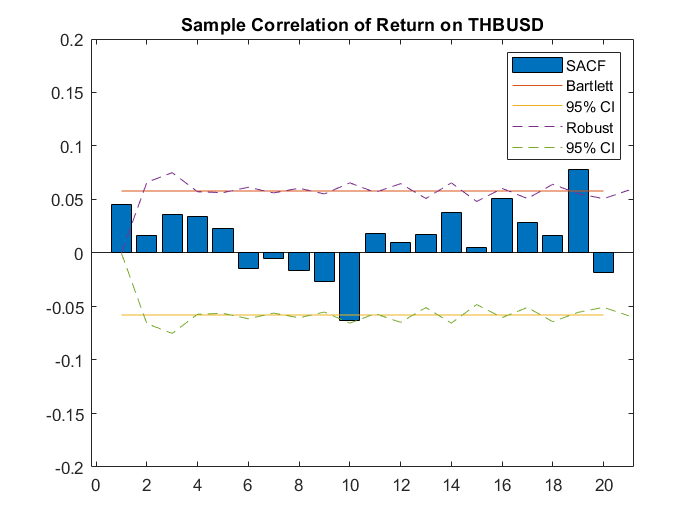

[Qstat1a, pval1a, corr1a] = LBtest(retthb,20);
[Qrbstat1a, prbval1a, rbci1a] = robustLBtest(retthb,20);

figure(1)
bar(corr1a(:,1))
title('Sample Correlation of Return on THBUSD')
hold on
plot(corr1a(:,3))
hold on
plot(-corr1a(:,3))
hold on
plot(rbci1a,'--')
hold on
plot(-rbci1a, '--')
ylim([-0.2 0.2])
legend('SACF','Bartlett','95% CI' ,'Robust','95% CI') 
hold off 

[Qstat1a, Qrbstat1a; 1-pval1a, 1-prbval1a]

ans =    26.2655   41.1117
    0.1572    0.0036


`Note:` The columns displayed the LB and the robust LB test results, respectively (chi-square statistic and p-value shown in order).

For the LB test, we fail to reject the null hypothesis at 5% level of significance, and that there is not sufficient evidence of predictability. However, for the robust LB, the result indicates some evidences of predictability at 5% level of significance.

- **Series 1B** - USDTHB (Squared Return)

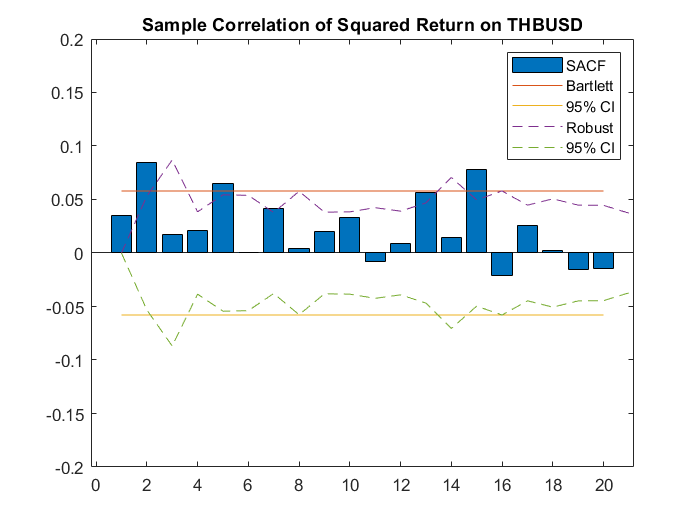

[Qstat1b, pval1b, corr1b] = LBtest(retthb_sq,20);
[Qrbstat1b, prbval1b, rbci1b] = robustLBtest(retthb_sq,20);

figure(2)
bar(corr1b(:,1))
title('Sample Correlation of Squared Return on THBUSD')
hold on
plot(corr1b(:,3))
hold on
plot(-corr1b(:,3))
hold on
plot(rbci1b,'--')
hold on
plot(-rbci1b, '--')
ylim([-0.2 0.2])
legend('SACF','Bartlett','95% CI' ,'Robust','95% CI') 
hold off 

[Qstat1b, Qrbstat1b; 1-pval1b, 1-prbval1b]

ans =    32.0307   40.0161
    0.0430    0.0050


`Note:` The columns displayed the LB and the robust LB test results, respectively (chi-square statistic and p-value shown in order).

We reject the null hypothesis in both LB and Robust LB Tests at 5% level of significance, and that there are some evidences of predictability. 

- **Series 2A** - Gold Price (Return)

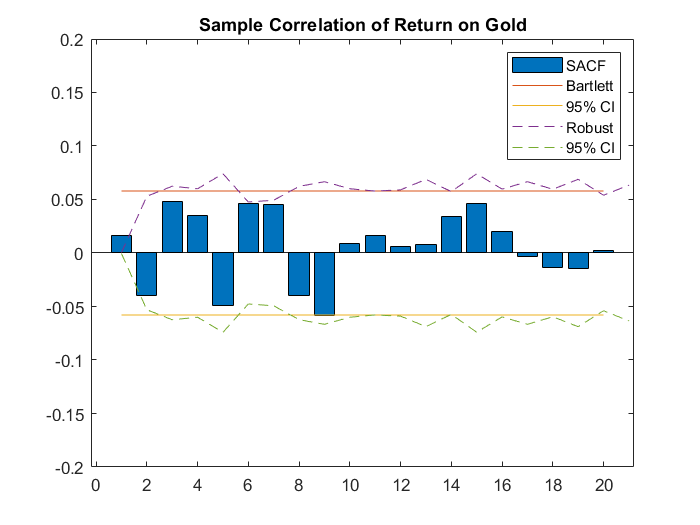

[Qstat2a, pval2a, corr2a] = LBtest(retgold,20);
[Qrbstat2a, prbval2a, rbci2a] = robustLBtest(retgold,20);

figure(3)
bar(corr2a(:,1))
title('Sample Correlation of Return on Gold')
hold on
plot(corr2a(:,3))
hold on
plot(-corr2a(:,3))
hold on
plot(rbci2a,'--')
hold on
plot(-rbci2a, '--')
ylim([-0.2 0.2])
legend('SACF','Bartlett','95% CI' ,'Robust','95% CI') 
hold off 

[Qstat2a, Qrbstat2a; 1-pval2a, 1-prbval2a]

ans =    24.9066   49.6370
    0.2050    0.0002


`Note:` The columns displayed the LB and the robust LB test results, respectively (chi-square statistic and p-value shown in order).

For the LB test, we fail to reject the null hypothesis at 5% level of significance, and that there is not sufficient evidence of predictability. However, for the robust LB, the result indicates some evidences of predictability at 5% level of significance.

- **Series 2B** - Gold Price (Squared Return)

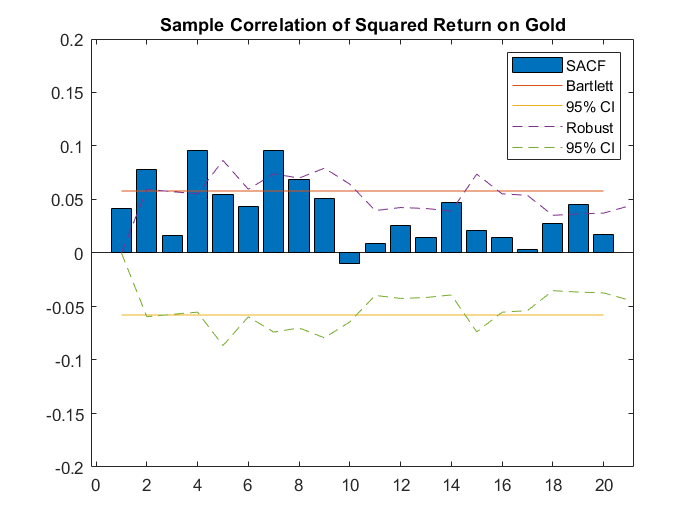

[Qstat2b, pval2b, corr2b] = LBtest(retgold_sq,20);
[Qrbstat2b, prbval2b, rbci2b] = robustLBtest(retgold_sq,20);

figure(4)
bar(corr2b(:,1))
title('Sample Correlation of Squared Return on Gold')
hold on
plot(corr2b(:,3))
hold on
plot(-corr2b(:,3))
hold on
plot(rbci2b,'--')
hold on
plot(-rbci2b, '--')
ylim([-0.2 0.2])
legend('SACF','Bartlett','95% CI' ,'Robust','95% CI') 
hold off 

[Qstat2b, Qrbstat2b; 1-pval2b, 1-prbval2b]

ans =    52.6241  144.2447
    0.0001         0


`Note:` The columns displayed the LB and the robust LB test results, respectively (chi-square statistic and p-value shown in order).

We reject the null hypothesis in both LB and Robust LB Tests at 5% level of significance, and that there are some evidences of predictability. 

- **Series 3A** - SET (Bangkok, Thailand) Index (Return)

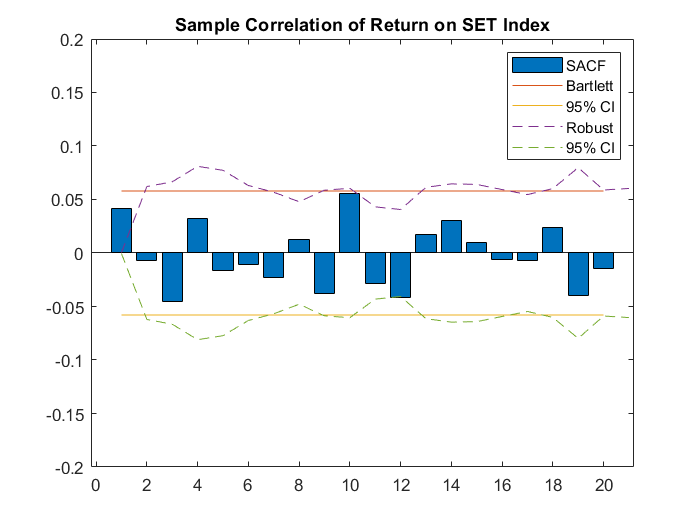

[Qstat3a, pval3a, corr3a] = LBtest(retset,20);
[Qrbstat3a, prbval3a, rbci3a] = robustLBtest(retset,20);

figure(5)
bar(corr3a(:,1))
title('Sample Correlation of Return on SET Index')
hold on
plot(corr3a(:,3))
hold on
plot(-corr3a(:,3))
hold on
plot(rbci3a,'--')
hold on
plot(-rbci3a, '--')
ylim([-0.2 0.2])
legend('SACF','Bartlett','95% CI' ,'Robust','95% CI') 
hold off 

[Qstat3a, Qrbstat3a; 1-pval3a, 1-prbval3a]

ans =    19.2007   27.7299
    0.5088    0.1159


`Note:` The columns displayed the LB and the robust LB test results, respectively (chi-square statistic and p-value shown in order).

We fail reject the null hypothesis in both LB and Robust LB Tests at 5% level of significance, and that there is no evidences of predictability. 

- **Series 3B** - SET (Bangkok, Thailand) Index (Squared Return)

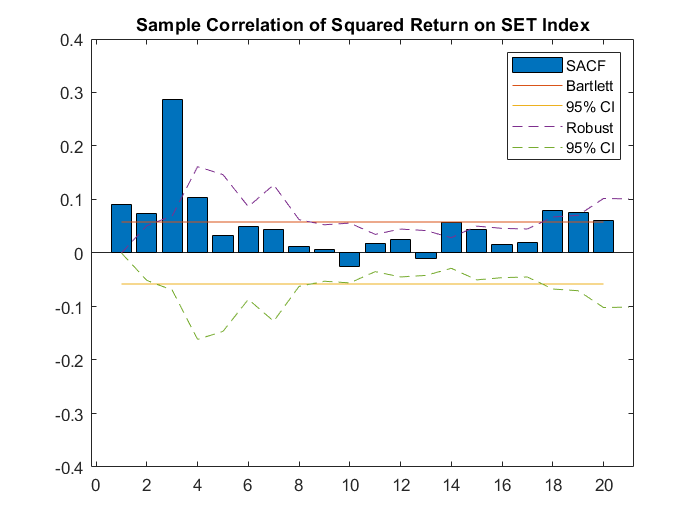

[Qstat3b, pval3b, corr3b] = LBtest(retset_sq,20);
[Qrbstat3b, prbval3b, rbci3b] = robustLBtest(retset_sq,20);

figure(6)
bar(corr3b(:,1))
title('Sample Correlation of Squared Return on SET Index')
hold on
plot(corr3b(:,3))
hold on
plot(-corr3b(:,3))
hold on
plot(rbci3b,'--')
hold on
plot(-rbci3b, '--')
ylim([-0.4 0.4])
legend('SACF','Bartlett','95% CI' ,'Robust','95% CI') 
hold off 

[Qstat3b, Qrbstat3b; 1-pval3b, 1-prbval3b]

ans =   155.3092   99.0965
         0    0.0000


`Note:` The columns displayed the LB and the robust LB test results, respectively (chi-square statistic and p-value shown in order).

We reject the null hypothesis in both LB and Robust LB Tests at 5% level of significance, and that there are some evidences of predictability. 

**Problem 2a - ***The x3 function*

%function [fx] = x3(~)

%    fx = @(x) abs(x)^3;
    
%end

**Problem 2b - ***Unconstrainted Minimization*

[argmin_,fval_min]= fminunc(x3, 2)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


argmin_ = 0.0020

fval_min = 8.3202e-09

**Problem 2c - ***Constrainted Minimization*

[argmincon_,fval_mincon] = fmincon(x3,3,-1,-1)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


argmincon_ = 1.0000

fval_mincon = 1.0000

**Problem 2d - ***The x4 function*

%function [gx] = x4(~)

%    gx = @(x) (2*(2-x^2)^2)+x;
    
%end

**Problem 2e - ***The Unconstraint Minimization x0 = 0*

[g1argmin_,g1val_min]= fminunc(x4, 0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


g1argmin_ = -1.4445

g1val_min = -1.4295

**Problem 2f - ***The Unconstraint Minimization x0 = 1*

[g2argmin_,g2val_min]= fminunc(x4, 1)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


g2argmin_ = 1.3819

g2val_min = 1.3982

**Problem 2g - ***The Plots*

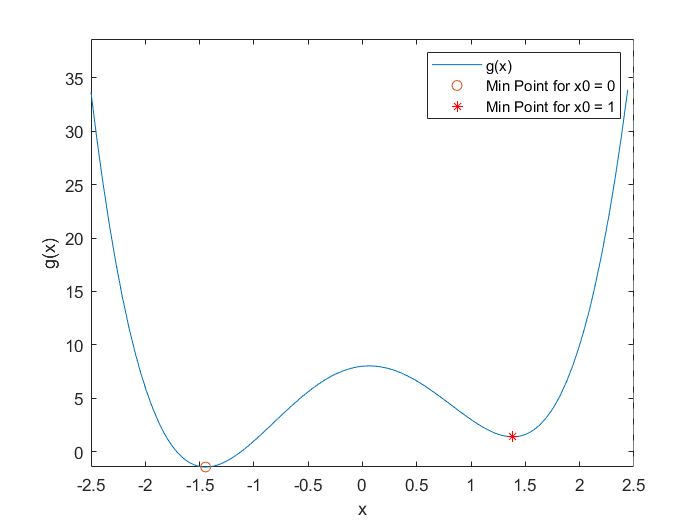

figure(7)
fplot(x4,[-2.5 2.5])
hold on
plot(g1argmin_,g1val_min,'o')
hold on
plot(g2argmin_,g2val_min,'r*')
xlabel('x')
ylabel('g(x)')
legend('g(x)','Min Point for x0 = 0','Min Point for x0 = 1')

**Problem 3a - *** The "Negative" Log-likelihood Function*

%function [loglikelihood] = LL_nomral(theta,X)
%
% theta = [mean, variance]
%
%
%T = size(X,1);

%logpdf = 0; 
%for t = 1:T 
%    logpdf = logpdf + log(1/(sqrt(theta(2)*2*pi)))*exp(-(X(t)-theta(1)^2/(2*theta(2));
%end

%loglikelihood = -logpdf;
%end

**Problem 3b - *** Estimates the MLE*

theta = [0;0];
[thetaMLE,LLval_min] = fmincon(@(theta)LL_nomral(theta,retthb),[1 ;1],[0 0;0 -1],[0;0])


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


thetaMLE = 	1.0e+-4 *

   -0.5434
    0.0873


LLval_min = -5.0307e+03

mean_thb = mean(retthb)

mean_thb = -5.4348e-05

var_thb = var(retthb)

var_thb = 8.7425e-06

**Note **that the MLE of mean and variance are nearly identical to the estimates using sample moments (the last two values).

**Problem 4 - *** GARCH*

- The GARCH function

% function [sigma2] = garch_variance(theta,data)
        %%theta = [omega, alpha, beta]
% T = size(data,1);
%sigma2 = zeros(T,1);
%sigma2(1) = var(data);
%
%    for t=2:T
%        sigma2(t) = theta(1) + theta(2)*data(t-1)^2 + theta(3)*sigma2(t-1);
%    end   
% end


- The reasonable choices of theta, namely, alpha, beta, and omega have to follow are constrained by;

-     
$$\begin{array}{l}
\alpha \ge 0,\;\beta \ge 0,\mathrm{and}\;\omega >0\;\;\;\;\left(\mathrm{For}\;\mathrm{positive}\;\mathrm{variances}\right)\\
\mathrm{If}\;\alpha =0,\mathrm{then}\;\beta =0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\mathrm{For}\;\mathrm{identification}\right)\\
\alpha +\beta <1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\mathrm{For}\;\mathrm{no}\;\mathrm{unit}\;\mathrm{root}\right)
\end{array}$$
 

- Let $\alpha \;=0\ldotp 1\;,\;\beta =0\ldotp 85,\mathrm{and}\;\omega =E\left\lbrack \varepsilon^2 \right\rbrack \;\;\;\;$

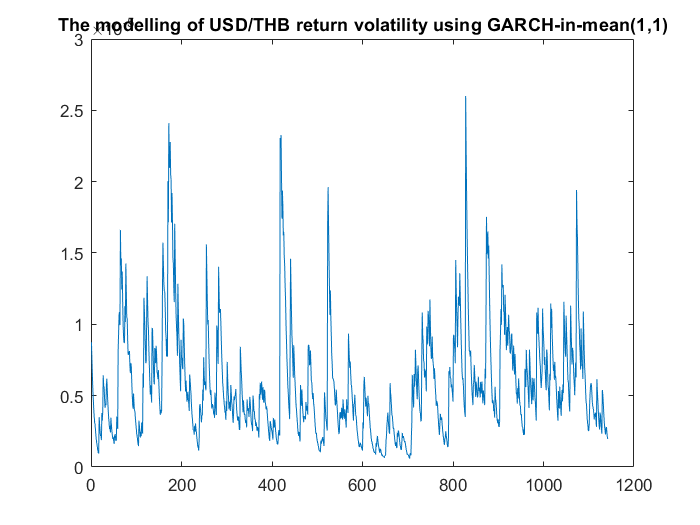

demean_thb = retthb - mean_thb;
% alpha + beta < 1, w > 0
grach_theta = [mean(demean_thb) 0.1 0.85];
garchmod = garch_variance(grach_theta ,demean_thb);

figure(8)
plot(garchmod)
title('The modelling of USD/THB return volatility using GARCH-in-mean(1,1)')

**Problem 5a - *** Demeaned S&P 500*

sp500 = csvread('gspc.csv', 1, 1);
retsp = price2ret(sp500(:, 5));
res_retsp = retsp - mean(retsp);

**Problem 5b - *** GARCH(1,1) Estimation using Pre-programmed Package from Oxford's MFE*

volmodel = garch(1,1);
est_garch = estimate(volmodel,res_retsp) 

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    1.688e-06     3.7487e-07        4.5028      6.7061e-06
    GARCH{1}      0.88459      0.0066918        132.19               0
    ARCH{1}       0.10287      0.0057105        18.015      1.4894e-72



est_garch =   garch with properties:

     Description: "GARCH(1,1) Conditional Variance Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               Q: 1
        Constant: 1.68799e-06
           GARCH: {0.884589} at lag [1]
            ARCH: {0.102874} at lag [1]
          Offset: 0

**Problem 5c - *** The Plots*

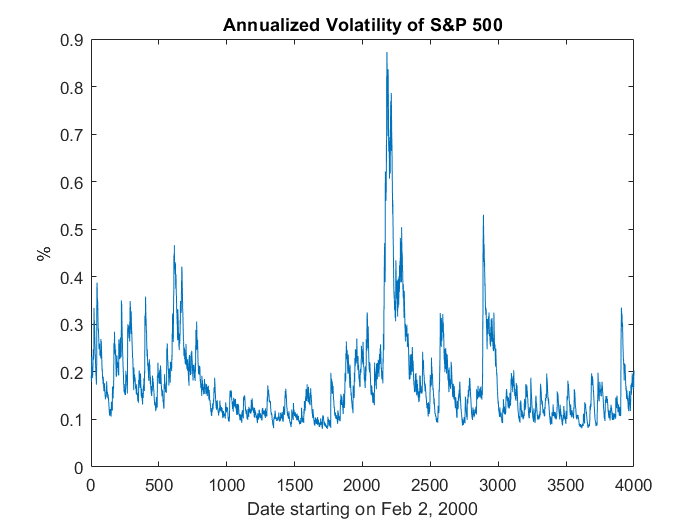

g_beta = cell2mat(est_garch.GARCH);
g_alpha = cell2mat(est_garch.ARCH);
g_omega = est_garch.Constant;

est_theta = [g_omega; g_alpha; g_beta];
garchfit = garch_variance(est_theta, res_retsp);
annvol = sqrt(252.*garchfit);
figure(9)

plot(annvol)
xlim([0 4000])
title('Annualized Volatility of S&P 500')
xlabel('Date starting on Feb 2, 2000')
ylabel('%')